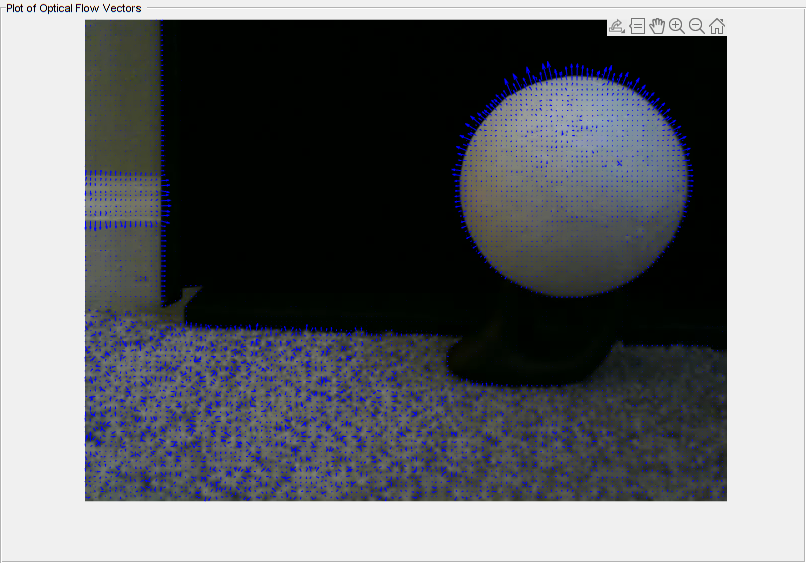

% Video file
videoFile = 'output.avi';

% Create a VideoReader object to read the video file
vidReader = VideoReader(videoFile);

% Specify the optical flow estimation method using Horn-Schunck algorithm
opticFlow = opticalFlowHS('Smoothness', 1, 'MaxIteration', 10, 'VelocityDifference', 0);

% Create a custom figure window to visualize the optical flow vectors
h = figure;
movegui(h, 'center'); % Position the GUI in the center of the screen
hViewPanel = uipanel('Parent', h, 'Position', [0 0 1 1], 'Title', 'Plot of Optical Flow Vectors');
hPlot = axes('Parent', hViewPanel);

% Define frame intervals for reference frame reset
intervals = [1, 11, 31];

% Loop over each interval
for k = 1:length(intervals)
    interval = intervals(k);
    referenceFrameCount = 0; % Counter to track when to reset reference frame

    % Reset video reader to the start of the video
    vidReader.CurrentTime = 0;

    % Reset optical flow estimator
    reset(opticFlow);

    % Process each frame in the video
    while hasFrame(vidReader)
        frameRGB = readFrame(vidReader); % Read the current frame from the video
        frameGray = rgb2gray(frameRGB); % Convert the frame to grayscale

        % Estimate the optical flow
        flow = estimateFlow(opticFlow, frameGray);

        % Update and display every n-th frame based on the current interval
        if mod(referenceFrameCount, interval) == 0
            % Reset optical flow for the new reference frame
            reset(opticFlow);
            flow = estimateFlow(opticFlow, frameGray);
        end

        % Plot the current frame and the optical flow vectors
        if mod(referenceFrameCount, 5) == 0  % Update visualization every 5 frames for clarity
            imshow(frameRGB, 'Parent', hPlot);
            hold on;
            plot(flow, 'DecimationFactor', [5 5], 'ScaleFactor', 60, 'Parent', hPlot);
            hold off;
            pause(0.001); % A short pause to allow visualization
        end

        referenceFrameCount = referenceFrameCount + 1; % Increment frame counter
    end

    % Pause between different interval processing for manual observation
    pause(2);
end